begin = 1;
ending = 4;
x_raw = rand(1,100);
x = sort(begin+(ending-begin)*x_raw);
fun = @(t) sin(t);


Рунге

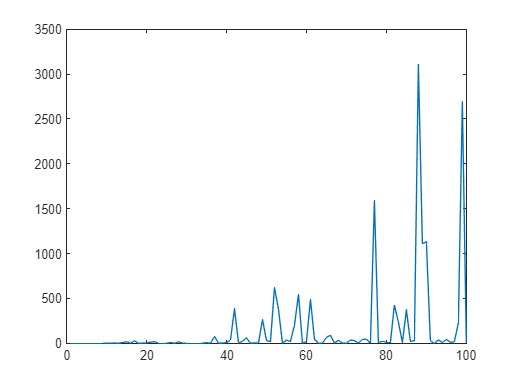

for n = 10:1:100
    x_rawtestrh = rand(1,n);
    x_testrh = sort(begin+(ending-begin)*x_rawtestrh);
    x_rawtesth2 = rand(1,n);
    x_testrh2 = sort(begin+(ending-begin)*x_rawtesth2);
    
    h = x_testrh(2)-x_testrh(1);
    h2 = x_testrh2(2)-x_testrh2(1);
    
    int_h = mid_rectangle(x_testrh, fun);
    int_h2 = mid_rectangle(x_testrh2, fun);
    
    C(n) = abs((int_h2-int_h)/(h^2-h2^2));
end
plot(C)

Уточнение по Ричардсону

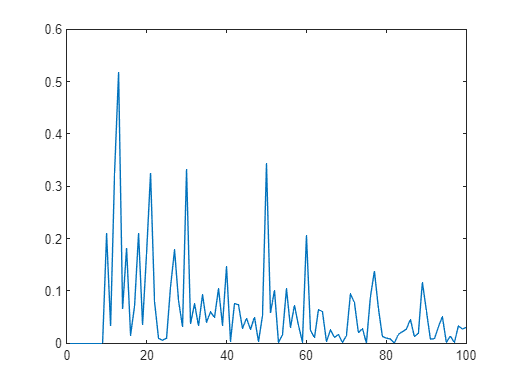

for n = 10:1:100
    x_rawtestrh = rand(1,n);
    x_testrh = sort(begin+(ending-begin)*x_rawtestrh);
    x_rawtesth2 = rand(1,n);
    x_testrh2 = sort(begin+(ending-begin)*x_rawtesth2);
    
    h = x_testrh(2)-x_testrh(1);
    
    int_h = mid_rectangle(x_testrh, fun);
    int_h2 = mid_rectangle(x_testrh2, fun);
    
%     deviath = abs(integral(fun, begin, ending) - int_h);
%     alphh = -log(deviath)/log(length(x_testrh));
   
    B(n) = abs(integral(fun, begin, ending) - (2^2*int_h2-int_h)/(2^2-1));
end
plot(B)